<<MODEL 1>>

Solving EOM for the first model  where the rod is of negligible mass and thus the mass of the pendulum is thought to be concentrated at the end:

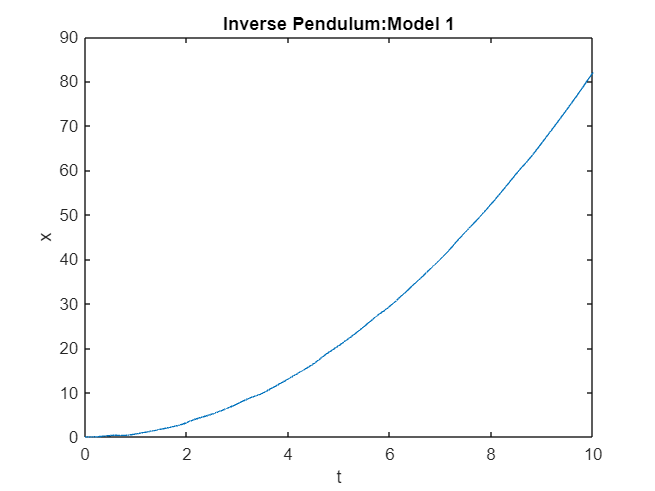

% SOLVE (M+m)dx2/dt2 + mldthdt2cos(th) - mldthdt^2sin(th) = F
% SOLVE mldx2/dt2costh + Aml^2dth/dt2 - mglsin(th) = 0
% initial conditions x(0) = 0, x'(0) = 0, th(0) = 0, th'(0) = 0
% mass concentrated at the end of the pendulum : A = 1

t = 0: 0.001 : 10;

initial_x1 = 0;
initial_x2 = 0;
initial_dx1dt = 0;
initial_dx2dt = 0;
A=1;
[t, x] = ode45(@inverse_pen, t, [initial_x1 initial_dx1dt initial_x2 initial_dx2dt]);

plot(t, x(:, 1));
title('Inverse Pendulum:Model 1');
xlabel('t'); ylabel('x');

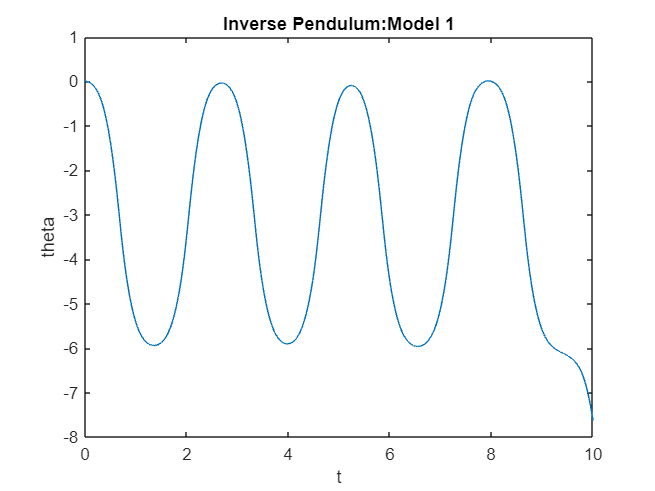

plot(t, x(:, 3));
title('Inverse Pendulum:Model 1');
xlabel('t'); ylabel('theta');

<<MODEL 2>>

Solving EOM for the second model where the pendulum part of the system is only modeled by a rigid rod(A = 4/3):

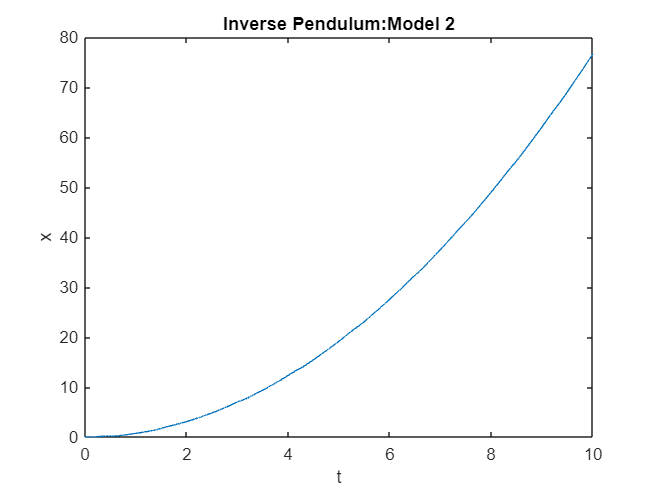

[t, x] = ode45(@inverse_pen_2, t, [initial_x1 initial_dx1dt initial_x2 initial_dx2dt]);

plot(t, x(:, 1));
title('Inverse Pendulum:Model 2');
xlabel('t'); ylabel('x');

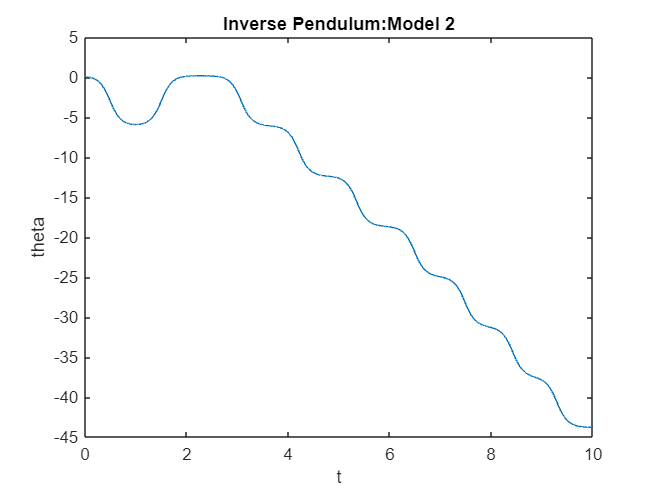

plot(t, x(:, 3));
title('Inverse Pendulum:Model 2');
xlabel('t'); ylabel('theta');

function dxdt = inverse_pen(t,x)
    M = 0.4;
    m = 0.2;
    l = 0.4;
    g = 9.8;
    F = 3;

    dxdt_1 = x(2);
    dxdt_2 = (-m*g*sin(x(3))*cos(x(3))+m*l*(x(4))^2*sin(x(3)) + F)/((M+m) - m*cos(x(3))^2);
    dxdt_3 = x(4);
    dxdt_4 = ( (M+m)*g*sin(x(3)) - l*m*l*(x(4))^2*sin(x(3))*cos(x(3)) - F*cos(x(3)))/((M+m)*l - m*l*(cos(x(3))^2));

    dxdt=[dxdt_1; dxdt_2; dxdt_3; dxdt_4];
end

function dxdt = inverse_pen_2(t,x)
    M = 0.4;
    m = 0.2;
    l = 0.2;
    g = 9.8;
    F = 3;
    A = 4/3;

    dxdt_1 = x(2);
    dxdt_2 = (-m*g*sin(x(3))*cos(x(3))+m*l*(x(4))^2*sin(x(3)) + F)/((M+m) - m*cos(x(3))^2/A);
    dxdt_3 = x(4);
    dxdt_4 = ( (M+m)*g*sin(x(3)) - l*m*l*(x(4))^2*sin(x(3))*cos(x(3)) - F*cos(x(3)))/((M+m)*l - m*l*(cos(x(3))^2)/A);

    dxdt=[dxdt_1; dxdt_2; dxdt_3; dxdt_4];
end
